Primeri za razdelek računanja determinante jacobijeve matrike za trikotne Coonsove ploskve.

export_images = false; % nastavi na false da se slike ne exportajo

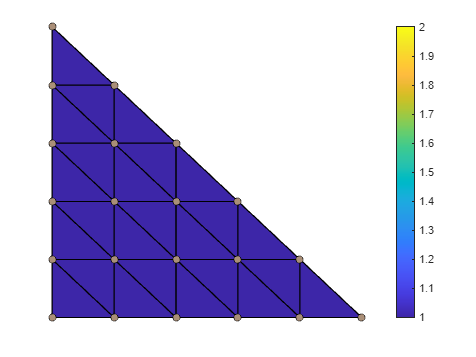

Bx = [1 2 3 4 5 6; 1 0 0 0 5 NaN; 1 0 0 4 NaN NaN; 1 0 3 NaN NaN NaN; 1 2 NaN NaN NaN NaN; 1 NaN NaN NaN NaN NaN];
By = Bx';

n = size(Bx,1) - 1;

[bx, by] = permanence_tri_patch(Bx, By, 0.2);

BX = bx';
BX = BX(:);
BX = BX(~isnan(BX));

BY = by';
BY = BY(:);
BY = BY(~isnan(BY));

[TRI, U] = trimeshgrid(60);

b = bezier3(bx, by, zeros(size(bx)), U);
J = calculate3_jacobi(bx, by, U);

b(:, 3) = J;

m = max(J) + 1;

tri = triangulation(TRI, b);

figure
trisurf(tri, 'EdgeColor', 'None');
hold on
trimesh(trimeshgrid(n), BX, BY, m * ones(size(BX)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX, BY, m * ones(size(BX)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on

colorbar

grid off
set(gca,'visible','off')

view([-0.50 90.00])


if export_images
    exportgraphics(gcf, 'j3_example1.pdf', 'ContentType', 'vector')
end

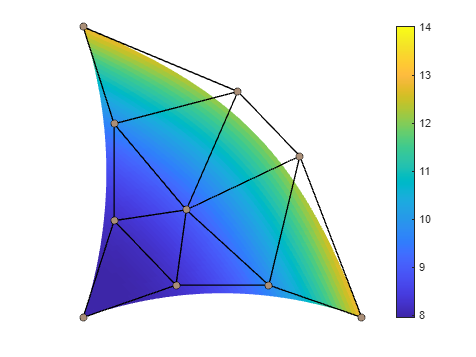

Bx = [1 4 7 10; 2 0 8 NaN; 2 6 NaN NaN; 1 NaN NaN NaN];
By = [1 2 2 1; 4 0 6 NaN; 7 8 NaN NaN; 10 NaN NaN NaN];

n = size(Bx,1) - 1;

[bx, by] = permanence_tri_patch(Bx, By, 0.2);

BX = bx';
BX = BX(:);
BX = BX(~isnan(BX));

BY = by';
BY = BY(:);
BY = BY(~isnan(BY));

[TRI, U] = trimeshgrid(60);

b = bezier3(bx, by, zeros(size(bx)), U);
J = calculate3_jacobi(bx, by, U);

b(:, 3) = J;

m = max(J) + 1;

tri = triangulation(TRI, b);

figure
trisurf(tri, 'EdgeColor', 'None');
hold on
trimesh(trimeshgrid(n), BX, BY, m * ones(size(BX)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX, BY, m * ones(size(BX)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
colorbar

grid off
set(gca,'visible','off')

view([-0.50 90.00])


if export_images
    exportgraphics(gcf, 'j3_example2.pdf', 'ContentType', 'vector')
end

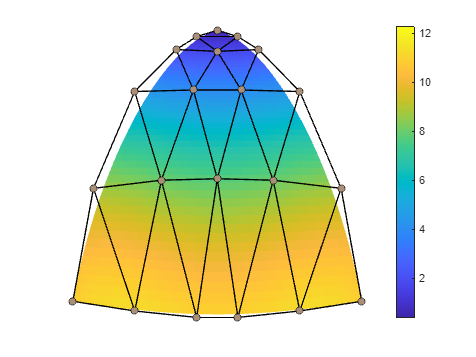

Bx = [1 4 7 9 12 15; 2 0 0 0 14 NaN; 4 0 0 12 NaN NaN; 6 0 10 NaN NaN NaN; 7 9 NaN NaN NaN NaN; 8 NaN NaN NaN NaN NaN];
By = [1.5 1.2 1 1 1.2 1.5; 5 0 0 0 5 NaN; 8 0 0 8 NaN NaN; 9.3 0 9.3 NaN NaN NaN; 9.7 9.7 NaN NaN NaN NaN; 9.9 NaN NaN NaN NaN NaN];

n = size(Bx,1) - 1;

[bx, by] = permanence_tri_patch(Bx, By, -0.2);

BX = bx';
BX = BX(:);
BX = BX(~isnan(BX));

BY = by';
BY = BY(:);
BY = BY(~isnan(BY));

[TRI, U] = trimeshgrid(60);

b = bezier3(bx, by, zeros(size(bx)), U);
J = calculate3_jacobi(bx, by, U);

b(:, 3) = J;

m = max(J) + 1;

tri = triangulation(TRI, b);

figure
trisurf(tri, 'EdgeColor', 'None');
hold on
trimesh(trimeshgrid(n), BX, BY, m * ones(size(BX)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX, BY, m * ones(size(BX)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
colorbar

grid off
set(gca,'visible','off')

view([-0.50 90.00])


if export_images
    exportgraphics(gcf, 'j3_example3.pdf', 'ContentType', 'vector')
end

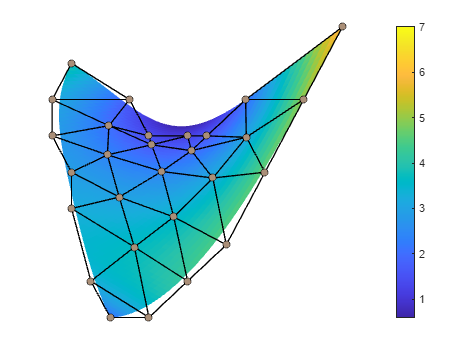

Bx = [2 4 6 8 10 12 14; 1 0 0 0 0 9 NaN; 0 0 0 0 7 NaN NaN; 0 0 0 6 NaN NaN NaN; -1 0 4 NaN  NaN NaN NaN; -1 3 NaN NaN NaN NaN NaN; 0 NaN NaN NaN NaN NaN NaN];
By = [0 0 1 2 4 6 8; 1 0 0 0 0 6 NaN; 3 0 0 0 5 NaN NaN; 4 0 0 5 NaN NaN NaN; 5 0 5 NaN  NaN NaN NaN; 6 6 NaN NaN NaN NaN NaN; 7 NaN NaN NaN NaN NaN NaN];

n = size(Bx,1) - 1;

[bx, by] = permanence_tri_patch(Bx, By, 0.2);

BX = bx';
BX = BX(:);
BX = BX(~isnan(BX));

BY = by';
BY = BY(:);
BY = BY(~isnan(BY));

[TRI, U] = trimeshgrid(60);

b = bezier3(bx, by, zeros(size(bx)), U);
J = calculate3_jacobi(bx, by, U);

b(:, 3) = J;

m = max(J) + 1;

tri = triangulation(TRI, b);

figure
trisurf(tri, 'EdgeColor', 'None');
hold on
trimesh(trimeshgrid(n), BX, BY, m * ones(size(BX)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX, BY, m * ones(size(BX)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
colorbar

grid off
set(gca,'visible','off')

view([-0.50 90.00])